# Import Messy Data from Fixed-Width Formatted Text File

Define an import options object to import messy data from a fixed-width formatted text file. Configure the object to handle the messy data and use it to import the table. 

## Load and Preview Fixed-Width Text File

Load the file `fixed_width_patients_subset_messy.txt` and preview its contents in a text editor. A screen shot is shown below. The screen shot shows that the file contains: 

- Empty lines – Lines 7, 12, and 13

- An extra column –  Column 8 

- Missing data – Lines 1, 4, 9 and 11

- Partial fields  – Last 3 rows

filename = 'fixed_width_patients_subset_messy.txt';

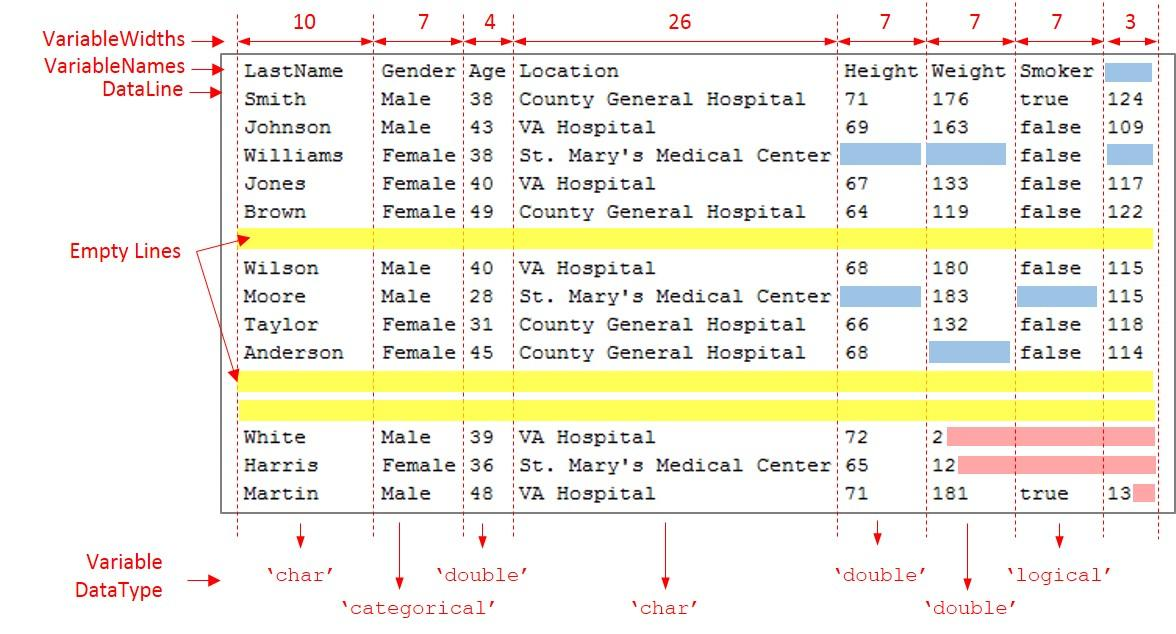

## Examine and Capture Properties of Fixed-Width File

The fixed-width text file has tabular data organized by the starting location, number of variables, variable names, and variable widths. Capture these properties and the data type you want to use for the variables. 

DataStartLine = 2;  
NumVariables = 7;
VariableNames  = {'LastName','Gender','Age','Location','Height',...
                                                      'Weight','Smoker'};
VariableWidths = [ 10,     7,     4,    26,     7, ...
                                                         7,     7 ] ;                                                  
DataType       = {'char','categorical','double','char','double',...
                                                     'double','logical'};

## Initialize `FixedWidthImportOptions` Object and Set Up Variable Properties

Initialize a `FixedWidthImportOptions` object and configure its properties to match the properties of the data. 

opts = fixedWidthImportOptions('NumVariables',NumVariables,...
                               'DataLines',DataStartLine,...
                               'VariableNames',VariableNames,...
                               'VariableWidths',VariableWidths,...
                               'VariableTypes',DataType);

## Set Up `EmptyLinesRule`,` Missing Rule`, and  `ExtraColumnsRule`

Read the empty lines in the data by setting the `EmptyLineRule` to  `'read'`. Next, fill the missing instances with predefined values by setting the `MissingRule`  to `'fill'`. Finally, to ignore the extra column during the import, set the `ExtraColumnsRule` to `'ignore'`.  For more information on the properties and their values, see documentation for `FixedWidthImportOptions`.  

opts.EmptyLineRule = 'read';
opts.MissingRule = 'fill'; 
opts.ExtraColumnsRule ='ignore';

## Set Up `PartialFieldRule`

Partial fields occur when the importing function reaches the end-of-line character before the full variable width is traversed. For example, in this preview, the last three rows from the file `fixed_width_patients_subset_messy.txt`. Here, in the last row of the last column, the end-of-line character appears after two places from the start of the field, before the full variable-width of three is reached. 

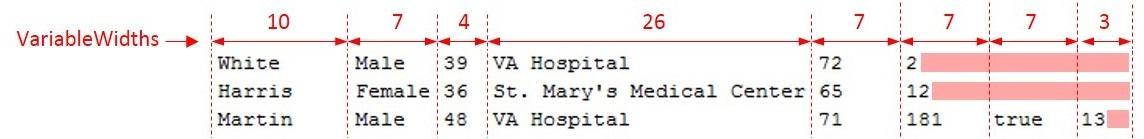

This occurrence of a partial field sometimes can indicate an error. Therefore, use the `PartialFieldRule` to decide how to handle this data. To keep the partial field data and convert it to the appropriate data type, set the `PartialFieldRule` to `'keep'`. For more information on the `PartialFieldRule`, see documentation for `FixedWidthImportOptions`.

opts.PartialFieldRule = 'keep';

## Import Table

Import the table by using `readtable` function and the `FixedWidthImportOptions` object and preview the data. 

T = readtable(filename,opts)

*Copyright 2012 The MathWorks, Inc.*